# **IO907 - Shared Memory Loopback**

This example shows you how to exchange data between two real-time target machines and how to synchronize these machines using the shared memory network interrupt. 

The IO907 I/O module is a fast, shared memory I/O module with Simulink® driver blocks, providing high-speed data transfer between two or multiple real-time target machines or third-party nodes.

The Simulink models used in this example feature the following blocks: [IO907 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_setup), [IO907 Broadcast](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_broadcast), [IO907 Read Interrupt Information](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_read_interrupt_information), [IO907 Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_write), [IO907 Read](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_read) and [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup).

## Setup

### Prerequisites

You will require the following to run this example:

- Two Speedgoat real-time target machines, each with one IO907 I/O module installed

- A fiber-optic LC-LC connector cable

### Test Setup

The node ID can be set with the S2 switch bank. Each IO907 must have a different ID in the shared memory network. The available IDs range from 0 to 0xFF (255 decimal). Switch position 1 corresponds to the least significant bit and switch position 8 to the most significant bit.

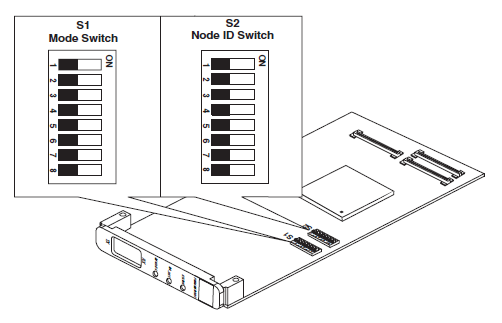

Each IO907 has two fiber optic connections, RX (receive) and TX (transmit). When connecting two systems, a crossed connection is required (mode used in this example). For networks with multiple nodes, a ring connection is required as the following schematic demonstrates:

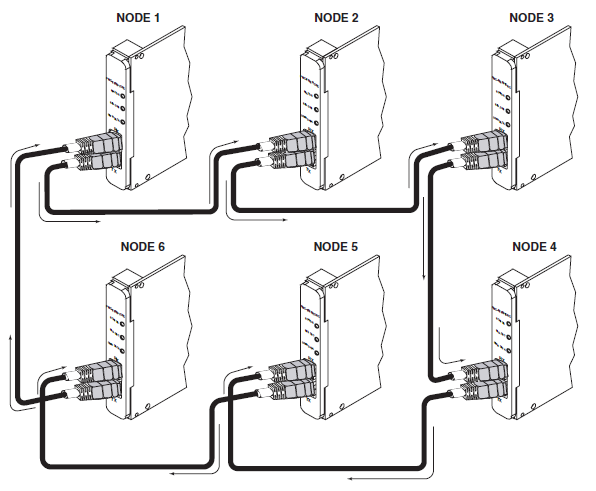

## Initialize and Open the Simulink model

 
% Make sure that all variables used in the model are defined by running the initialization script
% before opening the model 
run('IO907_InitPartitions.m');

% Create two Simulink models
modelName = 'sgMdl_IO907_SharedMemoryLoopback';
modelNameTg1 = 'sgMdl_IO907_Initiator';
modelNameTg2 = 'sgMdl_IO907_Node';
open_system(modelName);
save_system(modelName, modelNameTg1);
open_system(modelName);
save_system(modelName, modelNameTg2);

% Load main Simulink model
load_system(modelName);

% Prepare Simulink models for each target
Simulink.BlockDiagram.deleteContents(modelNameTg1);
Simulink.SubSystem.copyContentsToBlockDiagram([modelName, '/Initiator'], modelNameTg1);
pause(.5)
set_param(modelNameTg1, 'ZoomFactor', 'FitSystem');

% Set fundamental sample time and save Simulink model
set_param(modelNameTg1, 'FixedStep', '0.001');
save_system(modelNameTg1);

Simulink.BlockDiagram.deleteContents(modelNameTg2);
Simulink.SubSystem.copyContentsToBlockDiagram([modelName, '/Node'], modelNameTg2);
pause(.5)
set_param(modelNameTg2, 'ZoomFactor', 'FitSystem');

% Set fundamental sample time and save Simulink model
set_param(modelNameTg2, 'FixedStep', '0.001');
save_system(modelNameTg2);

close_system(modelName);

### Model Description

In the initiator model, a sine wave signal and a counter value are packed into a continuous array of 32-bit words using the [Shared Memory Pack](https://mathworks.com/help/slrealtime/io_ref/sharedmemorypack.html) block for subsequent transmission by the [IO907 Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_write) block. Partition one is used for the sine wave originating from the Initiator, partition two for the counter value signal. This data is transferred to the other IO907 over the shared memory network, where it is manipulated and sent back using partitions three and four. The partitions are initialized in the IO907_InitPartitions.m MATLAB script. The data received is unpacked using the [Shared Memory Unpack](https://mathworks.com/help/slrealtime/io_ref/sharedmemoryunpack.html) block in order to read the signals.

The network interrupt is used to synchronize the second real-time target machine over the shared memory network. Each time the [IO907 Broadcast](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io907_broadcast) block is executed, an interrupt packet is sent to all the nodes in the network using the interrupt ID 1.

In the node model, the data from partitions one and two are manipulated and written to partitions three and four. The entire model is triggered by the network interrupt, issued by the initiator model. The interrupt source ID must be initialized in the IO907_InitPartitions.m MATLAB script and configured in the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) block by selecting the **Speedgoat IO907 interrupt**. 

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelNameTg1);
slbuild(modelNameTg2);

% Create and connect to the Speedgoat real-time target machine
tg1 = slrealtime('TargetPC1');
tg1.connect;
tg2 = slrealtime('TargetPC2');
tg2.connect;

% Download and install the real-time application on the target machine
tg1.load(modelNameTg1);
tg2.load(modelNameTg2);

% Initialize SDI
Simulink.sdi.setSubPlotLayout(2,1);
Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;

% Start the real-time application
tg2.start;
tg1.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg1.stop;
tg2.stop;

% Display data
runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:2
    plotOnSubPlot(sigsobj(k),k,1,true);
end

### Check the Results

To check if the data exchange over the network is working as expected, open the Simulink scope connected to the [Shared Memory Unpack](https://mathworks.com/help/slrealtime/io_ref/sharedmemoryunpack.html) block. In the scope, a sine wave signal and a counter signal (represented by the green line) must be displayed:

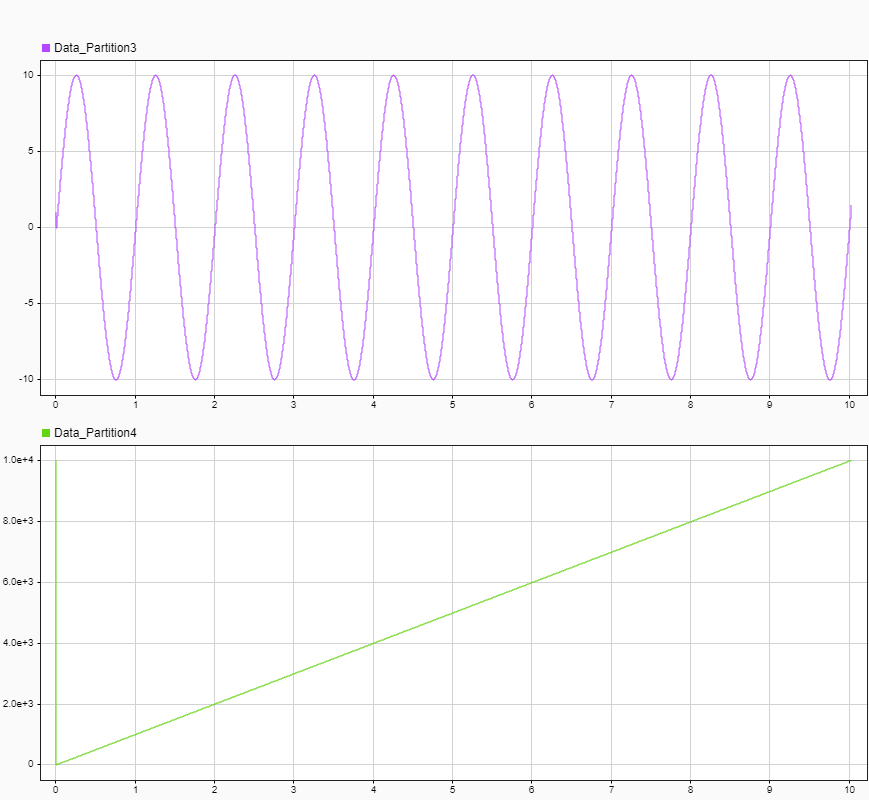

## Additional References

- [IO907 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io907)